Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Bunch-lengthening simulation (Section 12.5)

Volker Ziemann, 211123

In this example we discuss a simulation, suggested by Hirata in [97], where we follow the centroid and sigma-matrix of the longitudinal phases-space distribution of an electron beam as it experiences synchrotron oscillations, radiation damping and excitation, and a  localized source of wake fields. The simulation uses normalized coordinates explained in Section 12.5.

We first define the parameters of the simulation, the synchrotron phase advance per turn `nus`, the damping time` Nd` in units of turns in the ring, and the strength of the wake `f0,` which is proportional to the impedance of the wake and the single-bunch beam current.

clear all
nus=0.12345;      % synchrotron phase advance
U=[cos(nus),sin(nus);-sin(nus),cos(nus)];   % rotation matrix
Nd=1000;          % longitudinal radiation damping time in turns
xi=exp(-1/Nd);    % damping decrement per turn
f0=0              % Slider to set strength of the wake

f0 = 0

Then we define the equilibrium beam size in the normalized coordinates and the duration of the simulation as 10 damping times. We also allocate the array `data` to store the values we later display.

sig0=1;              % equilibrium bunch length 
Nsim=10*Nd;          % Duration of the simulation
data=zeros(Nsim,3);  % allocate space for plotting

Then we define the initial conditions of the bunch distribution, which comes with an incorrct ariival time $X_1$ and has a mismatched beam matrix `sigma`, which differs from the unit matrix.

X=[1;0];              % wrong arrival time
sigma=[2,0.5;0.5,1];  % initial distribution

Now we iterate over `Nsim` turns and in each iteration we apply synchrotron oscillations, radiation damping and excitation,  as well as the map for the localized wake. At the end of the turn we copy the final values back to the initial variables `X` and `sigma`, and store some parameters in the array data for later display.

for k=1:Nsim
  [X2,sigma2]=hirata_synosc(U,X,sigma);
  [X3,sigma3]=hirata_radamp(xi,sig0,X2,sigma2);
  [X4,sigma4]=hirata_wake(f0,X3,sigma3);
  X=X4; sigma=sigma4;             % copy back
  data(k,1)=X(1);                 % arrival phase
  data(k,2)=sqrt(sigma(1,1));     % bunch length
  data(k,3)=sqrt(sigma(2,2));     % momentum spread
end

After the loop over the Nsim turns completes, we display the arrival phase $X_1$ in the upper plot. Bunch length and momentum spread are shown in the lower plot.

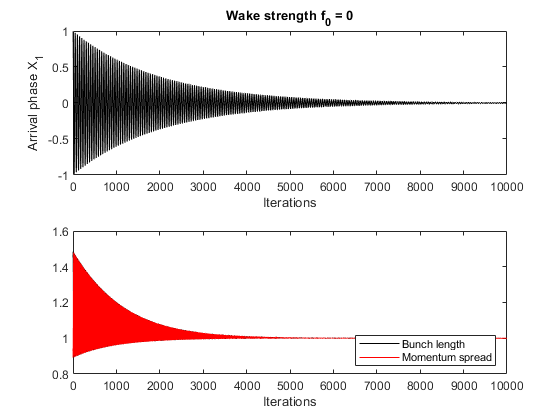

subplot(2,1,1); plot(1:Nsim,data(:,1),'k');
ylabel('Arrival phase X_1'); xlabel('Iterations'); 
title(['Wake strength f_0 = ',num2str(f0)])
subplot(2,1,2); plot(1:Nsim,data(:,2),'k',1:Nsim,data(:,3),'r')
xlabel('Iterations'); 
legend('Bunch length','Momentum spread','Location','SouthEast')

Initially the wake strength `f0` is set to zero and we find that $X_1$ in the upper plot performs dampend synchrotron oscillations towards the equilibrium phase zero. Likewise, bunch length and momentum spread oscillate and are damped towards their equilibrium values, which is unity in the scaled variables.

Now it's time to move the slider to increase `f0` and observe how the phase, bunch length and momentum spread damp towards different equilibrium values as a consequence.  We therefore analyze the equilibrium values as a function of the wake strength `f0` in the next section.

#### Equilibrium bunch length and momentum spread

First we specify the range of values for `f0` to probe, allocate an array `data` for storage and set the initial values for `X` and `sigma` to their equilibrium values.

figure
f0=0.0:0.01:3;              % range of values to probe
data=zeros(length(f0),2);
X=[0;0]; sigma=[1,0;0,1];   % initial values for f0=0

Then we iterate the the combined map of synchrotron oscillation, radiation damping, and wake for three damping times `Nd` with `hirata_iterate()`, which is defined in the Appendix. In each iteration we store bunch length and momentum spread for later display. Note also that we use the final values of `X` and `sigma` for one value of `f0` as input for the next iteration, which guarantees rapid convergence.

for k=1:length(f0)
  [X,sigma]=hirata_iterate(3*Nd,U,xi,sig0,f0(k),X,sigma);
  data(k,1)=sqrt(sigma(1,1));
  data(k,2)=sqrt(sigma(2,2));
end

After the loop completes, we plot the bunch length $\sqrt{\sigma_{11}}$ and the momentum spread $\sqrt{\sigma_{22}}$ as a function of the wake strength `f0` and annotate the axes.

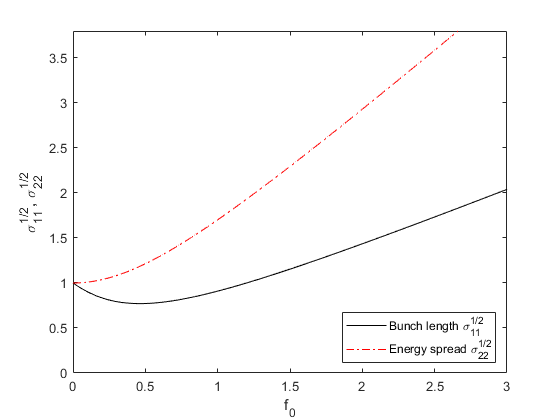

plot(f0,data(:,1),'k',f0,data(:,2),'r-.')
xlabel('f_0'); ylabel('\sigma_{11}^{1/2}, \sigma_{22}^{1/2}')
legend('Bunch length \sigma_{11}^{1/2}','Energy spread \sigma_{22}^{1/2}', ...
 'Location','SouthEast')
ylim([0,3.8])

Note how the bunch length is actually shortened for small values of f0, which is an indication of potential well distortion, which is discussed further in Section 12.5

## Appendix

#### hirata_synosc.m()

The function `hirata_synosc()` receives the matrix `U` that describes synchrotron oscillations, the centroid `X,` and the beam matrix `sigma` as input. It returns the centroid and sigma after the one oscillation, as described by Equation 12.21.

function [X2,sigma2]=hirata_synosc(U,X,sigma)
X2=U*X;
sigma2=U*sigma*U';
end

#### hirata_radamp()

The function `hirata_radamp()` receives the damping decrement `xi` and equilibrium bunch size `sig0` as input, as well as `X` and `sigma`. It returns the centroid and sigma after applying Equation 12.22.

function [X2,sigma2]=hirata_radamp(xi,sig0,X,sigma);
X2=[X(1);xi*X(2)];
sigma2=sigma;
sigma2(1,2)=xi*sigma(1,2); 
sigma2(2,1)=sigma2(1,2);
sigma2(2,2)=xi^2*sigma(2,2)+(1-xi^2)*sig0^2;
end

#### hirata_wake()

The function `hirata_wake()` receives the strength of the wake f0, as well as `X` and `sigma` as input.  It returns the centroid and sigma after applying Equation 12.23.

function [X2,sigma2]=hirata_wake(f0,X,sigma)
X2=[X(1);X(2)-0.5*f0];
sigma2=sigma;
sigma2(1,2)=sigma(1,2)-0.5*f0*sqrt(sigma(1,1))/sqrt(pi);
sigma2(2,1)=sigma2(1,2);
sigma2(2,2)=sigma(2,2)-f0*sigma(1,2)/sqrt(pi*sigma(1,1))+f0^2/12;
end

#### hirata_iterate()

The function `hirata_wake()` receives the number of turns `N` and the parameters `U, xi, sig0, f0` of the simulation as input as well as the initial values of  `X` and `sigma.` It returns the centroid `X` and `sigma` after iterating the map for synchrotron oscillations, radiation damping and excitation, as well as wake for `N` turns.

function [X,sigma]=hirata_iterate(N,U,xi,sig0,f0,X,sigma)
for k=1:N
  [X2,sigma2]=hirata_synosc(U,X,sigma);
  [X3,sigma3]=hirata_radamp(xi,sig0,X2,sigma2);
  [X4,sigma4]=hirata_wake(f0,X3,sigma3);
  X=X4; sigma=sigma4;
end
end